## Scalar variables

clear
format short

Scalar real variables can be created as follows:

r1=3

r1 = 3

r2=4

r2 = 4

r3=5

r3 = 5

r4=6;

Basic arithmetic operations on scalar real variables:

sum12=r1+r2

sum12 = 7

diff12=r1-r2

diff12 = -1

prod12=r1*r2

prod12 = 12

quot12=r1/r2

quot12 = 0.7500

power12=r1^r2

power12 = 81

prodsum1=r1*r2+r3

prodsum1 = 17

prodsum2=r1*(r2+r3)

prodsum2 = 27

To define an imaginary part of a complex variable, the `i` and `j` letters can be used:

c1=1+1i

c1 = 1.0000 + 1.0000i

c2=2-2j

c2 = 2.0000 - 2.0000i

Basic arithmetic operations on scalar complex variables:

sum12=c1+c2

sum12 = 3.0000 - 1.0000i

diff12=c1-c2

diff12 = -1.0000 + 3.0000i

prod12=c1*c2

prod12 = 4

quot12=c1/c2

quot12 = 0.0000 + 0.5000i

In the case of a complex variable, operator `'` (apostrophe) returns its complex conjugate:

c1conj=c1'

c1conj = 1.0000 - 1.0000i

Function `real` returns the real part of a complex variable, function `imag` returns the imaginary part of a complex variable, function `abs` returns the absolute value of a complex variable, while the function `angle` returns the argument of that variable:

realpart=real(c1)

realpart = 1

imagpart=imag(c1)

imagpart = 1

modulus=abs(c1)

modulus = 1.4142

argument=angle(c1)

argument = 0.7854

## Symbolic variables

Symbolic variables can be created by means of the `syms` function:

syms a b c x v
f=a*x^2+b*x+c

$$f = a\,x^{2}+b\,x+c$$

Function `subs` can be used to substitute a symbolic variable with a numerical value or with another symbolic expression:

a1=subs(f,a,1)

$$a1 = x^{2}+b\,x+c$$

derivative=diff(a1,x)

$$derivative = b+2\,x$$

f=subs(f,[a,b,c],[1,-3,2])

$$f = x^{2}-3\,x+2$$

integral=int(f,x)

$$integral = \frac{x\,\left(2\,x^{2}-9\,x+12\right)}{6}$$

funv=subs(f,x^2,v)

$$funv = v-3\,x+2$$

Substitution x = 2:

forx2=subs(f,x,2)

$$forx2 = 0$$

forx2d=double(forx2)

forx2d = 0

Solving an equation by means of the `solve` function:

rootsf=solve(f)

$$rootsf = \left(\begin{array}{c} 1\\ 2 \end{array}\right)$$

solution=solve(f==2)

$$solution = \left(\begin{array}{c} 0\\ 3 \end{array}\right)$$

Function `fplot` can be used to draw a graph of a function:

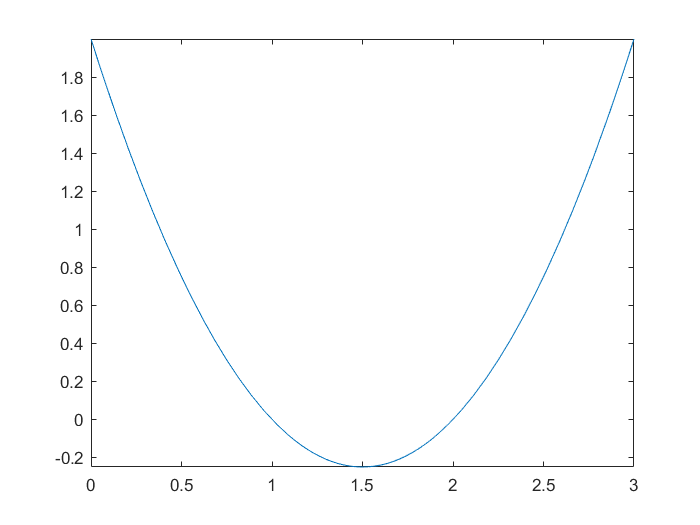

fplot(f,[0,3])

Symbolic variables are exact, *i.e.* they are not corrupted with rounding errors:

c3=sym(c1)
realpart=real(c3)
imagpart=imag(c3)
modulus=abs(c3)
argument=angle(c3)
argumentd=double(argument)

## Matrix variables

MATLAB is an environment oriented on matrix manipulation. It is not necessary to declare the dimensions of a matrix; during initialisation, the elements in the same row are separated with comma while the rows are separated with semicolon:

A=[1,2,3;4,5,6;7,8,9] 

A =      1     2     3
     4     5     6
     7     8     9


The elemet in `n`-th row and `m`-th column can be returned by means of the expression `A(n,m):`

A(2,3)

ans = 6

All the elements in `n`-th row or `m`-th column can be returned by means of the expressions `A(n,:)` and `A(:,m) `respectively:

A(2,:)

ans =      4     5     6


A(:,3)

ans =      3
     6
     9


An arbitrary subset (submatrix) of a matrix can be returned as follows:

A(2:3,1:2)

ans =      4     5
     7     8


A(2:end,1:end-1)

ans =      4     5
     7     8


Logical expressions can also be used to select the subset of the elements:

A(A==5)=99

A =      1     2     3
     4    99     6
     7     8     9


A(A<5)=0

A =      0     0     0
     0    99     6
     7     8     9


Variables can be overwritten even if they size and type do not match, *e.g*. after the execution of the following line the matrix `A` becomes a scalar variable:

A=A(2,3)

A = 6

Vectors can be created analogously to matrices; row vector:

a1=[1,2,3,4,5,6,7,8,9]

a1 =      1     2     3     4     5     6     7     8     9


column vector:

a2=[1;2;3;4;5;6;7;8;9]

a2 =      1
     2
     3
     4
     5
     6
     7
     8
     9


Vector `a1` can also be created in a different way:

a1=1:9

a1 =      1     2     3     4     5     6     7     8     9


a2=(1:9)'

a2 =      1
     2
     3
     4
     5
     6
     7
     8
     9


In the case of real-valued matrices and vectors, the operator ' (apostrophe) can be used for transposition:

A=[1,2;3,4;5,6;7,8]

A =      1     2
     3     4
     5     6
     7     8


a=[1,2,3,4,5,6,7,8,9]

a =      1     2     3     4     5     6     7     8     9


AT=A'

AT =      1     3     5     7
     2     4     6     8


at=a'

at =      1
     2
     3
     4
     5
     6
     7
     8
     9


In the case of complex-valued matrices and vectors, the operator `'` can be used for conjugate (Hermitian) transposition, while the transposition without conjugation is done by means of the `.'` operator:

Z=[1+1j,2-2j;3-3j,4+4j]

Z =    1.0000 + 1.0000i   2.0000 - 2.0000i
   3.0000 - 3.0000i   4.0000 + 4.0000i


Z'

ans =    1.0000 - 1.0000i   3.0000 + 3.0000i
   2.0000 + 2.0000i   4.0000 - 4.0000i


Z.'

ans =    1.0000 + 1.0000i   3.0000 - 3.0000i
   2.0000 - 2.0000i   4.0000 + 4.0000i


Matrices can be concatenated but only if their dimensions agree:

B=[1,2,3;4,5,6;7,8,9]

B =      1     2     3
     4     5     6
     7     8     9


C=[B,B]

C =      1     2     3     1     2     3
     4     5     6     4     5     6
     7     8     9     7     8     9


D=[B;B]

D =      1     2     3
     4     5     6
     7     8     9
     1     2     3
     4     5     6
     7     8     9


If the dimensions do not agree, MATLAB will throw an error:

E=[C,D]

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

If we try to define an element whose indexes exceed the matrix bounds, MATLAB will automatically enlarge that matrix to a proper size and set the values of the other undefined elements to zeros:

B(4,5)=10

B =      1     2     3     0     0
     4     5     6     0     0
     7     8     9     0     0
     0     0     0     0    10


However, if we try to refer to a non-existing element, MATLAB will throw an error:

B(6,7)   

Index in position 1 exceeds array bounds (must not exceed 4).

In MATLAB, there are many functions generating some widely used matrices, *e.g.*:

A=zeros(5) 

A =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


C=ones(3,6) 

C =      1     1     1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1


D=eye(4) 

D =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


E=rand(10,1)

E =     0.0975
    0.2785
    0.5469
    0.9575
    0.9649
    0.1576
    0.9706
    0.9572
    0.4854
    0.8003


F=ones(3)+3*eye(3)

F =      4     1     1
     1     4     1
     1     1     4


Examples of operations that can be performed on matrix elements:

C(1,2:3)=-1

C =      1    -1    -1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1


E(6:end)=1

E =     0.0975
    0.2785
    0.5469
    0.9575
    0.9649
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


F(end,1:end-1)=-1

F =      4     1     1
     1     4     1
    -1    -1     4


G=fliplr(F) 

G =      1     1     4
     1     4     1
     4    -1    -1


G=flipud(F)

G =     -1    -1     4
     1     4     1
     4     1     1


sizeofC=size(C)

sizeofC =      3     6


N=numel(F)

N = 9

Arithmetic operations on matrices:

A=[1,2,3;4,5,6;7,8,9] 

A =      1     2     3
     4     5     6
     7     8     9


B=[2,3,4;5,6,7;8,9,10]

B =      2     3     4
     5     6     7
     8     9    10


Addition: 

sumAB=A+B

sumAB =      3     5     7
     9    11    13
    15    17    19


Subtraction:

diffBA=B-A

diffBA =      1     1     1
     1     1     1
     1     1     1


Matrix multiplication is not commutative:

prodAB=A*B

prodAB =     36    42    48
    81    96   111
   126   150   174


prodBA=B*A

prodBA =     42    51    60
    78    96   114
   114   141   168


Element-wise matrix multiplication:

ewprodAB=A.*B

ewprodAB =      2     6    12
    20    30    42
    56    72    90


In MATLAB, the operator `\` (left-division operator) is used for solving a system of linear equations. For example, the following system:

`6*x1 -   x2 - 2*x3 = -51/25`

`  x1 + 2*x2        =  21/100`

`2*x1 + 3*x2 - 2*x3 = -42/25`

can be written in the vector-matrix form **A*****x**=**b**, where **A** denotes the matrix of equation coefficients

A=[6,-1,-2;1,2,0;2,3,-2]

A =      6    -1    -2
     1     2     0
     2     3    -2


**x** denotes the vector of the unknown variables, while **b** denotes the vector of solutions:

b=[-2.04;0.21;-1.68]

b =    -2.0400
    0.2100
   -1.6800


The above-defined system of linear equations can be solved by means of the left-division operator \:

x=A\b

x =     0.0100
    0.1000
    1.0000


Let's check the obtained solution:

error=A*x-b

error = 	1.0e+-15 *

         0
   -0.1943
         0


Let's check it again using symbolic variables:

A=sym(A)

$$A = \left(\begin{array}{ccc} 6 & -1 & -2\\ 1 & 2 & 0\\ 2 & 3 & -2 \end{array}\right)$$

b=sym(b)

$$b = \left(\begin{array}{c} -\frac{51}{25}\\ \frac{21}{100}\\ -\frac{42}{25} \end{array}\right)$$

x=A\b

$$x = \left(\begin{array}{c} \frac{1}{100}\\ \frac{1}{10}\\ 1 \end{array}\right)$$

error=A*x-b

$$error = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Element-wise matrix division:

A=[1,2,3;4,5,6;7,8,9]

A =      1     2     3
     4     5     6
     7     8     9


B=[2,3,4;5,6,7;8,9,10]

B =      2     3     4
     5     6     7
     8     9    10


ewdivAB=A./B 

ewdivAB =     0.5000    0.6667    0.7500
    0.8000    0.8333    0.8571
    0.8750    0.8889    0.9000


Matrix power defined as the matrix product of two copies of A:

matpow2=A^2

matpow2 =     30    36    42
    66    81    96
   102   126   150


Element-wise matrix power:

ewmatpow2=A.^2

ewmatpow2 =      1     4     9
    16    25    36
    49    64    81


Matrix inverse may be determined by means of `inv` function or by means of -1 power:

A=[3,2;1,3]

A =      3     2
     1     3


inv(A)

ans =     0.4286   -0.2857
   -0.1429    0.4286


A^(-1)

ans =     0.4286   -0.2857
   -0.1429    0.4286


We can also operate on symbolic matrix variables:

A=sym([3,2;1,3])

$$A = \left(\begin{array}{cc} 3 & 2\\ 1 & 3 \end{array}\right)$$

inv(A)

$$ans = \left(\begin{array}{cc} \frac{3}{7} & -\frac{2}{7}\\ -\frac{1}{7} & \frac{3}{7} \end{array}\right)$$

A system of linear equations can be solved by means of symbolic variables:

syms x1 x2
eqn1=x1+x2==2

$$eqn1 = x_{1}+x_{2}=2$$

eqn2=x1-x2==0

$$eqn2 = x_{1}-x_{2}=0$$

sol = solve([eqn1, eqn2], [x1, x2])

sol = struct with fields:
    x1: [1×1 sym]
    x2: [1×1 sym]


sol.x1

$$ans = 1$$

sol.x2

$$ans = 1$$

## Miscellaneous

Unfortunately, MATLAB allows for some operations which are not allowed in matrix algebra, e.g. addition/subtraction of two vectors of different orientations or vectors with different sizes; therefore, special care must be taken to obtaine meaningful results:

x=[1, 2, 3, 4]'

x =      1
     2
     3
     4


y=[1, 2, 3, 4]

y =      1     2     3     4


xmy=x-y

xmy =      0    -1    -2    -3
     1     0    -1    -2
     2     1     0    -1
     3     2     1     0


ymx=y-x

ymx =      0     1     2     3
    -1     0     1     2
    -2    -1     0     1
    -3    -2    -1     0


xpy=x+y

xpy =      2     3     4     5
     3     4     5     6
     4     5     6     7
     5     6     7     8


x=[1, 2, 3]'

x =      1
     2
     3


y=[1, 2, 3, 4]

y =      1     2     3     4


xmy=x-y

xmy =      0    -1    -2    -3
     1     0    -1    -2
     2     1     0    -1


ymx=y-x

ymx =      0     1     2     3
    -1     0     1     2
    -2    -1     0     1


xpy=x+y

xpy =      2     3     4     5
     3     4     5     6
     4     5     6     7
